# Display Robustness Outcomes

## Sparsity tuning (rho/lambda)

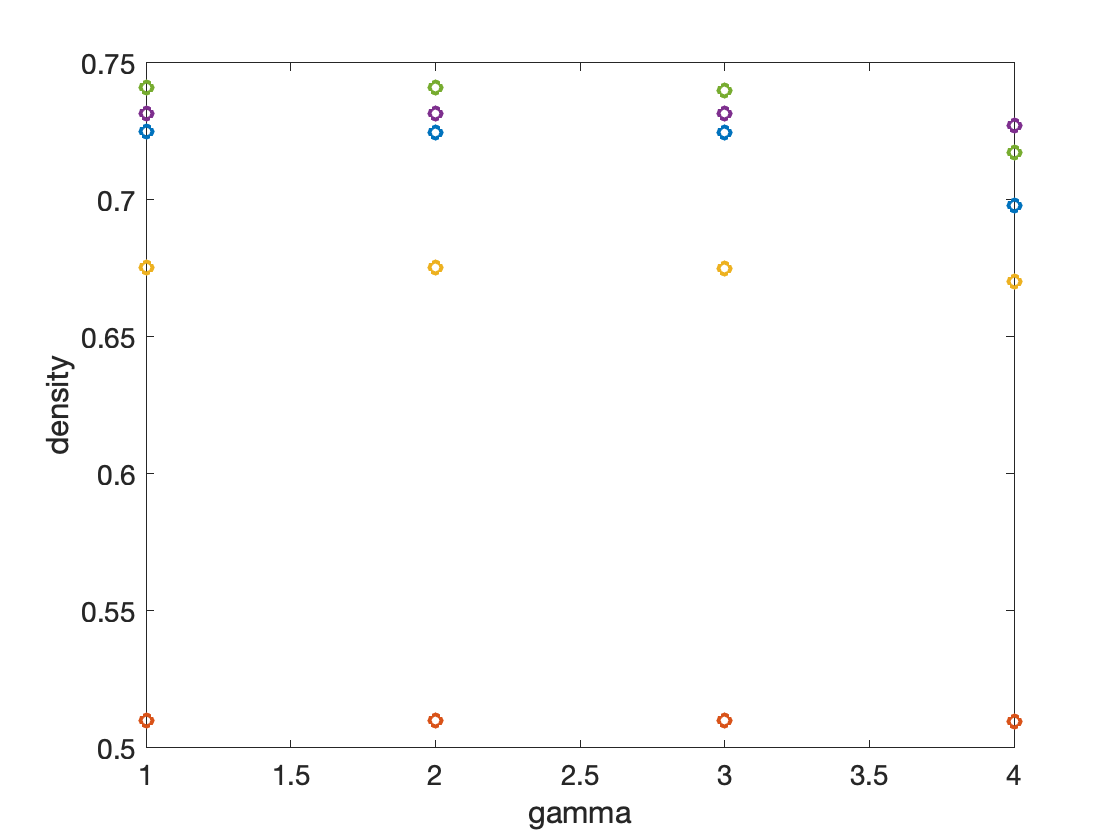

%Density vs. rho for each patient
gammas={'0','0_1','0_25', '0_5'};
for g=1:length(gammas)
    for i_pt=1:length(Network)
        load(sprintf('Data/Robustness/Network_%s.mat',gammas{g}))
        pcm= Network(i_pt).pcm;
        d(g,i_pt)=sum(pcm(:)~=0)./numel(pcm);
    end
end

plot(d)
xlabel('gamma'); ylabel('density')

## Contiguity Tuning (beta)

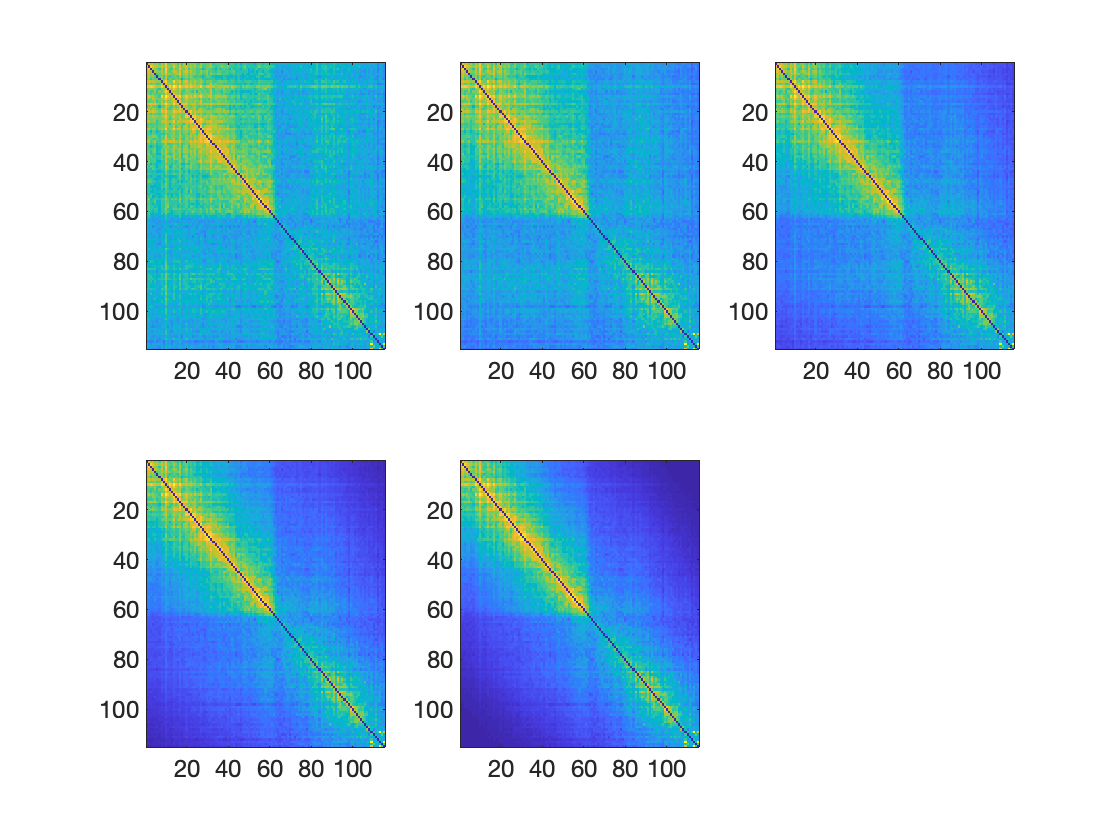


load('Data/Robustness/Network_0_5.mat')

fields={'0_1','0_25', '0_5', '0_75', '1'};
figure(2)
for i=1:5
    subplot(2,3,i)
    imagesc(Network(1).(['wSim_', fields{i}]))
end

## new heading

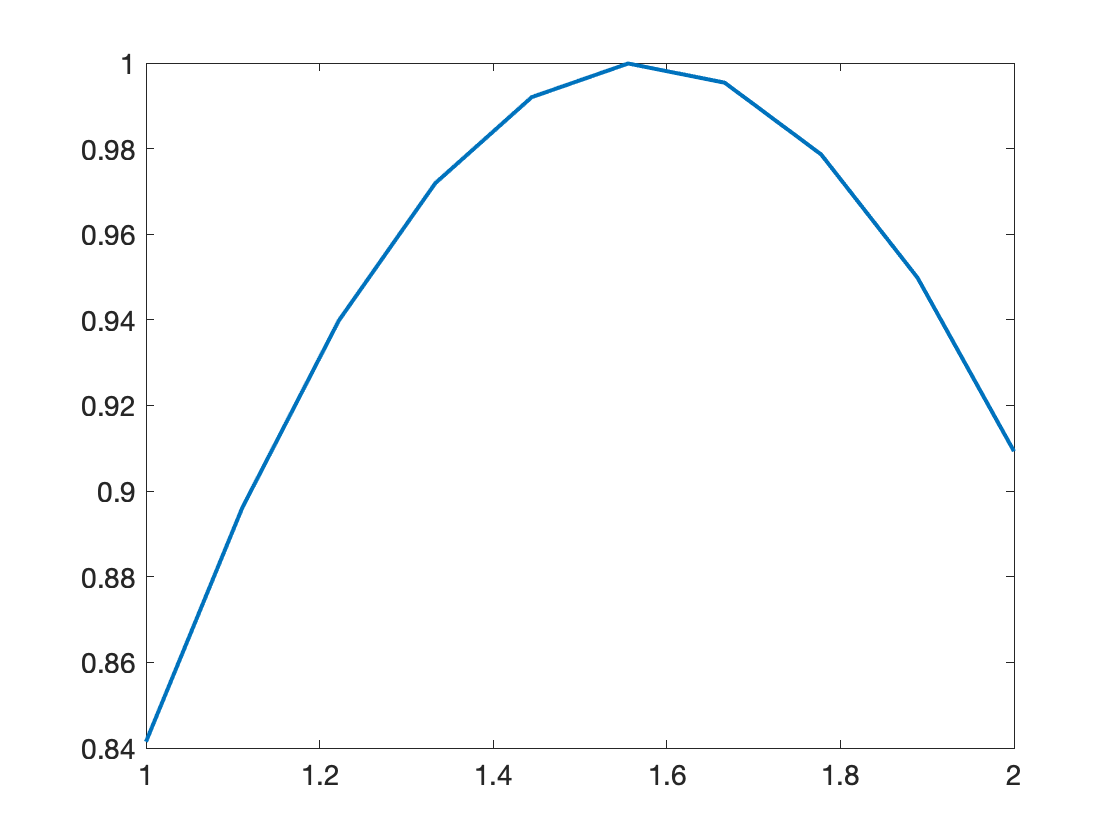

figure(3)
plot(linspace(1,2,10), sin(linspace(1,2,10)))